# SYED MUHAMMAD ZAIN 329876 ASSIGNMENT 2 ML

clc
clear all

## LOADING TRAINING DATA 

Train=load('E:\NUST\Semester 2\machine learning\assignment 2\Assignment-2\training.mat');
data=Train.T1% loaded training data with labels

data =     1.0000    2.0000    3.0000    4.0000    5.0000
    1.8799    3.9806   11.3801   16.2361   15.8526
    1.2033    4.9943   11.1115   16.2165   16.5716
    6.5747    6.8397    7.7595   13.9087   19.3205
   -1.3333    5.2996    6.9346   13.2022   19.2333
   -2.7086    7.8099    7.8043   13.2312   16.5367
   -1.2814    7.0682    7.1685   17.5606   20.7227
   -1.1867    5.5831   10.1191    9.4410   25.0661
    0.1328    3.4446    9.1775   14.3781   18.9953
    0.6631    6.1334    9.2640   15.8111   19.1817


## DATA PREPROCESSING 

labels=data(1,:)%labels 

labels =      1     2     3     4     5


data1=data;%making copy of the training data
data1(1,:)=[]%removing the first column

data1 =     1.8799    3.9806   11.3801   16.2361   15.8526
    1.2033    4.9943   11.1115   16.2165   16.5716
    6.5747    6.8397    7.7595   13.9087   19.3205
   -1.3333    5.2996    6.9346   13.2022   19.2333
   -2.7086    7.8099    7.8043   13.2312   16.5367
   -1.2814    7.0682    7.1685   17.5606   20.7227
   -1.1867    5.5831   10.1191    9.4410   25.0661
    0.1328    3.4446    9.1775   14.3781   18.9953
    0.6631    6.1334    9.2640   15.8111   19.1817
    0.5629    2.2348    7.2781   13.0417   11.1939


N=numel(data1)% total no of elements in training set 

N = 500

## MAKING CLASSES FROM TRAIN DATA

class1=data1(:,1);
class2=data1(:,2);
class3=data1(:,3);
class4=data1(:,4);
class5=data1(:,5);

## PLOTTING HISTOGRAMS

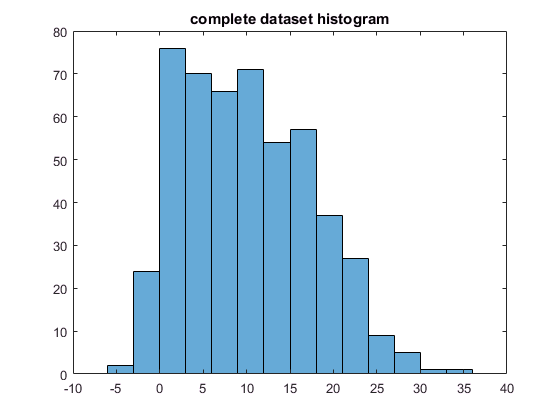

histogram(data1)
title('complete dataset histogram')

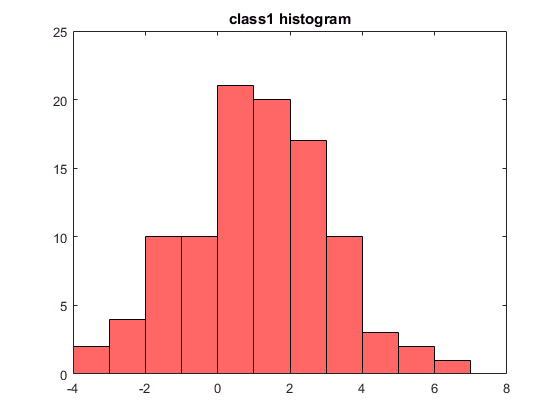

histogram(class1,'FaceColor','r')%class one histogram
title('class1 histogram')

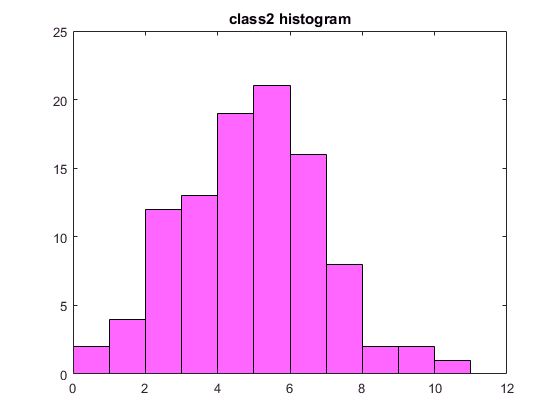

histogram(class2,'FaceColor','m')%class 2 histogram
title('class2 histogram')

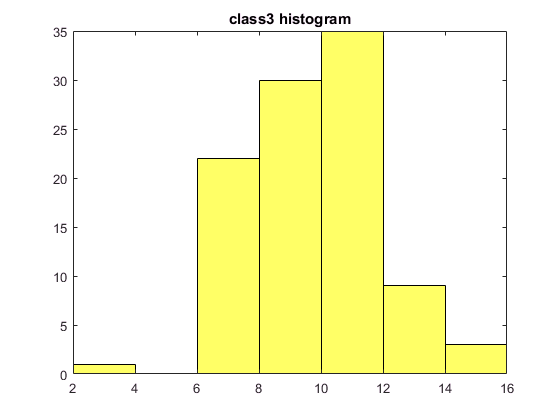

histogram(class3,'FaceColor','y')%class 3 histogram
title('class3 histogram')

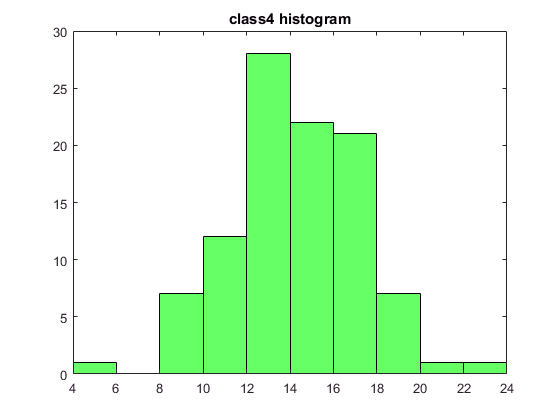

histogram(class4,'FaceColor','g')%class 4 histogram
title('class4 histogram')

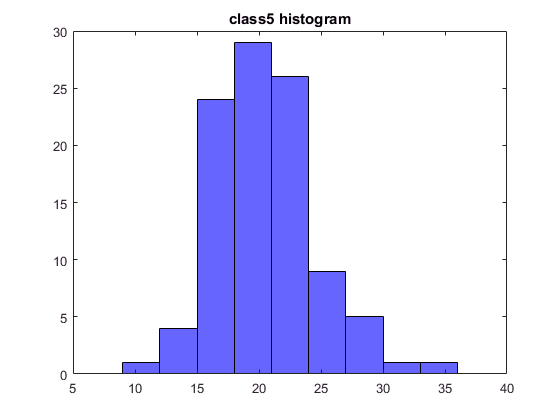

histogram(class5,'FaceColor','b')%class 5 histogram
title('class5 histogram')

## FINDING SUMMATION OF R(LABEL) SIGMAS AND MEANS OF CLASSES AS well AS PRIORS

## CLEARLY THE HISTOGRAMS ARE GAUSSIAN BASED 

%summation of r label for each class
r1=numel(class1);
r2=numel(class2);
r3=numel(class3);
r4=numel(class4);
r5=numel(class5);

%priors for each class
prior1=r1/N;
prior2=r2/N;
prior3=r3/N;
prior4=r4/N;
prior5=r5/N;

%means of all the classes(estimated)
mean1=sum(class1)/r1;
mean2=sum(class2)/r2;
mean3=sum(class3)/r3;
mean4=sum(class4)/r4;
mean5=sum(class5)/r5;

%sigma of the other classes
var1=sum((class1-mean1).^2)/r1;
var2=sum((class2-mean2).^2)/r2;
var3=sum((class3-mean3).^2)/r3;
var4=sum((class4-mean4).^2)/r4;
var5=sum((class5-mean5).^2)/r5;
s1=sqrt(var1);
s2=sqrt(var2);
s3=sqrt(var3);
s4=sqrt(var4);
s5=sqrt(var5);

%for plotting of the pdfs of each class
pd1=makedist('Normal','mu',mean1,'sigma',s1);
pd2=makedist('Normal','mu',mean2,'sigma',s2);
pd3=makedist('Normal','mu',mean3,'sigma',s3);
pd4=makedist('Normal','mu',mean4,'sigma',s4);
pd5=makedist('Normal','mu',mean5,'sigma',s5);
dummy=-35:1:35;
pdf1=pdf(pd1,dummy);
pdf2=pdf(pd2,dummy);
pdf3=pdf(pd3,dummy);
pdf4=pdf(pd4,dummy);
pdf5=pdf(pd5,dummy);

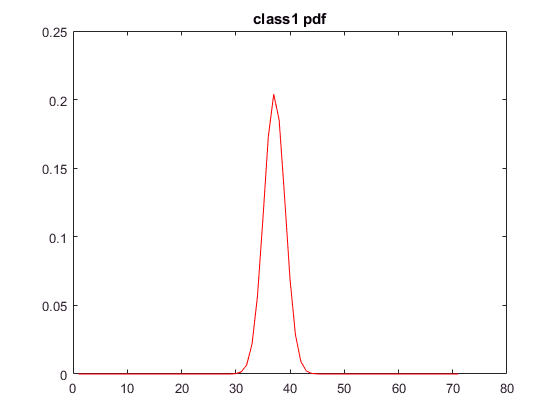

%pdf class 1
plot(pdf1,'color','r')
title('class1 pdf')

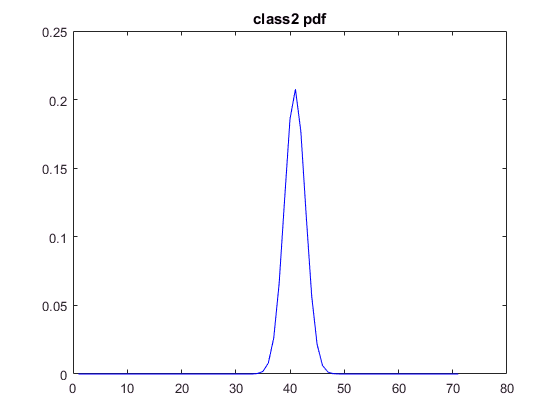

%pdf class 2
plot(pdf2,'color','b')
title('class2 pdf')

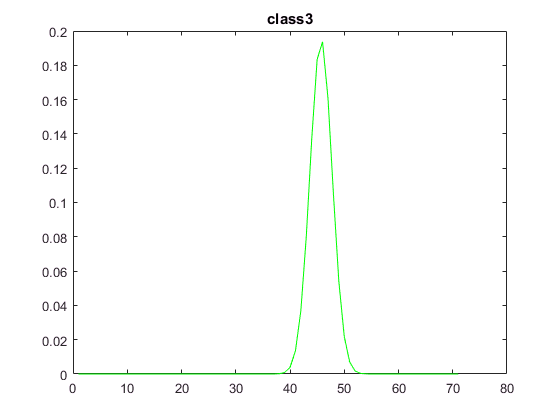

%pdf class 3
plot(pdf3,'color','g')
title('class3')

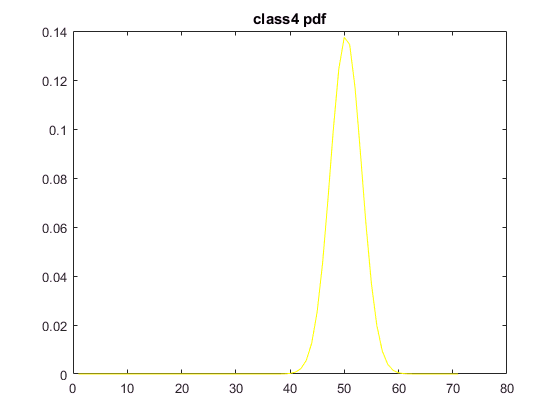

%pdf class 4
plot(pdf4,'color','y')
title('class4 pdf')

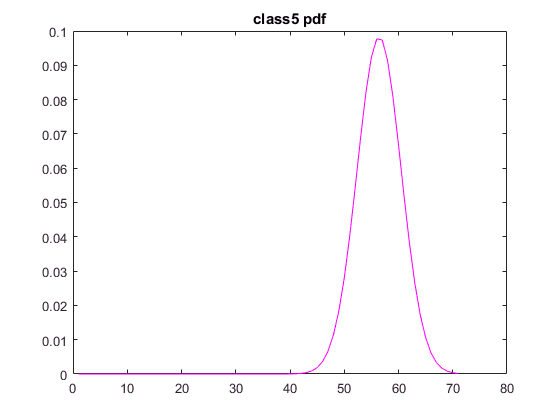

%pdf class 5
plot(pdf5,'color','m')
title('class5 pdf')

## Finding likelihoods and posteriors plus plotting posteriors

%likelihoods using dummy for better symmteric performance
L1=exp(-(dummy-mean1).^2./(2*var1))./(s1*sqrt(2*pi));
L2=exp(-(dummy-mean2).^2./(2*var2))./(s2*sqrt(2*pi));
L3=exp(-(dummy-mean3).^2./(2*var3))./(s3*sqrt(2*pi));
L4=exp(-(dummy-mean4).^2./(2*var4))./(s4*sqrt(2*pi));
L5=exp(-(dummy-mean5).^2./(2*var5))./(s5*sqrt(2*pi));

%posterior probabilites
%p(Ci)P(x|ci)
p1=L1*prior1;
p2=L2*prior2;
p3=L3*prior3;
p4=L4*prior4;
p5=L5*prior5;
TotalP=p1+p2+p3+p4+p5;%p(x)
%P(Ci|x) posterior
post1=p1./TotalP;
post2=p2./TotalP;
post3=p3./TotalP;
post4=p4./TotalP;
post5=p5./TotalP;

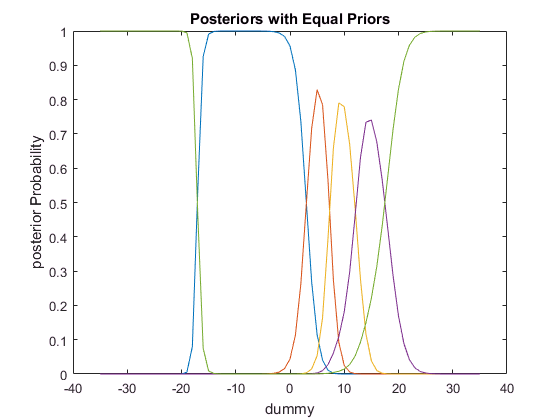

%plotting different posteriors together
plot(dummy,post1)
hold on
plot(dummy,post2);
hold on
plot(dummy,post3);
hold on
plot(dummy,post4);
hold on
plot(dummy,post5);
hold off
xlabel('dummy')
ylabel('posterior Probability')
title('Posteriors with Equal Priors')

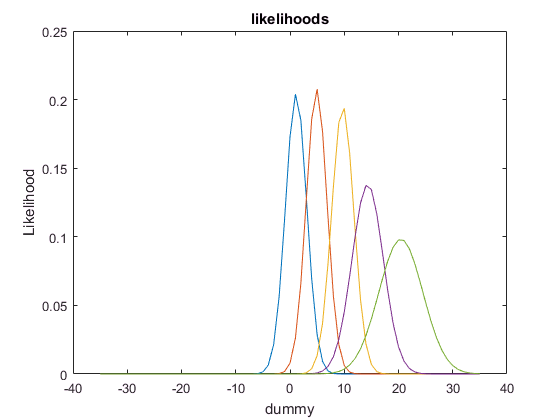

%plotting different posteriors together
plot(dummy,L1)
hold on
plot(dummy,L2);
hold on
plot(dummy,L3);
hold on
plot(dummy,L4);
hold on
plot(dummy,L5);
hold off
xlabel('dummy')
ylabel('Likelihood')
title('likelihoods')

## Discriminant Points

%class 1 and 2 and 2 1
a=(1/(2*var1))-(1/(2*var2));
b=(mean2/var2)-(mean1/var1);
c=((mean1^2)/(2*var1))-((mean2^2)/(2*var2))-(log10(s1/s2));
root1=(-b-sqrt(b^2-4*a*c))/(2*a);
root2=(-b+sqrt(b^2-4*a*c))/(2*a);
%class 1 and 3 
a=(1/(2*var1))-(1/(2*var3));
b=(mean3/var3)-(mean1/var1);
c=((mean1^2)/(2*var1))-((mean3^2)/(2*var3))-(log10(s1/s3));
root3=(-b-sqrt(b^2-4*a*c))/(2*a);
root4=(-b+sqrt(b^2-4*a*c))/(2*a);
%class 1 and 4
a=(1/(2*var1))-(1/(2*var4));
b=(mean4/var4)-(mean1/var1);
c=((mean1^2)/(2*var1))-((mean4^2)/(2*var4))-(log10(s1/s4));
root5=(-b-sqrt(b^2-4*a*c))/(2*a);
root6=(-b+sqrt(b^2-4*a*c))/(2*a);
%class 1 and 5 
a=(1/(2*var1))-(1/(2*var5));
b=(mean5/var5)-(mean1/var1);
c=((mean1^2)/(2*var1))-((mean5^2)/(2*var5))-(log10(s1/s5));
root7=(-b-sqrt(b^2-4*a*c))/(2*a);
root8=(-b+sqrt(b^2-4*a*c))/(2*a);
%class 2 and 3
a=(1/(2*var2))-(1/(2*var3));
b=(mean3/var3)-(mean2/var2);
c=((mean2^2)/(2*var2))-((mean3^2)/(2*var3))-(log10(s2/s3));
root9=(-b-sqrt(b^2-4*a*c))/(2*a);
root10=(-b+sqrt(b^2-4*a*c))/(2*a);
%class 2 and 4
a=(1/(2*var2))-(1/(2*var4));
b=(mean4/var4)-(mean2/var2);
c=((mean2^2)/(2*var2))-((mean4^2)/(2*var4))-(log10(s2/s4));
root11=(-b-sqrt(b^2-4*a*c))/(2*a);
root12=(-b+sqrt(b^2-4*a*c))/(2*a);
%class 2 and 5 
a=(1/(2*var2))-(1/(2*var5));
b=(mean5/var5)-(mean2/var2);
c=((mean2^2)/(2*var2))-((mean5^2)/(2*var5))-(log10(s2/s5));
root13=(-b-sqrt(b^2-4*a*c))/(2*a);
root14=(-b+sqrt(b^2-4*a*c))/(2*a);
%class 3 and 4
a=(1/(2*var3))-(1/(2*var4));
b=(mean4/var4)-(mean3/var3);
c=((mean3^2)/(2*var3))-((mean4^2)/(2*var4))-(log10(s3/s4));
root15=(-b-sqrt(b^2-4*a*c))/(2*a);
root16=(-b+sqrt(b^2-4*a*c))/(2*a);
%class 3 and 5 
a=(1/(2*var3))-(1/(2*var5));
b=(mean5/var5)-(mean3/var3);
c=((mean3^2)/(2*var3))-((mean5^2)/(2*var5))-(log10(s3/s5));
root17=(-b-sqrt(b^2-4*a*c))/(2*a);
root18=(-b+sqrt(b^2-4*a*c))/(2*a);
%class 4 and 5 
a=(1/(2*var4))-(1/(2*var5));
b=(mean5/var5)-(mean4/var4);
c=((mean4^2)/(2*var4))-((mean5^2)/(2*var5))-(log10(s4/s5));
root19=(-b-sqrt(b^2-4*a*c))/(2*a);
root20=(-b+sqrt(b^2-4*a*c))/(2*a);

Table1=table(root2,root4,root6,root8,root10,root12,root14,root16,root18,root20)%useful discriminant points

Table1 = 1×10 table
    root2     root4     root6     root8     root10    root12    root14    root16    root18    root20
    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    3.0418    5.3231    6.3789    7.2687    7.2217    8.5626    9.7295    11.434    13.077    16.572


%setting up plot accounting  for offsets in roots to make discriminants more near
% y and y1 values are found using data marker offset adjustments using data marker as well
%some roots required minor adjustments in them to make them accurate enough
discriminant2=root2;
discriminant4=root4;
discriminant6=root6;
discriminant8=root8+0.5313;
discriminant10=root10;
discriminant12=root12+0.4374;
discriminant14=root14+0.6205;
discriminant16=root16+0.716;
discriminant18=root18+0.823;
discriminant20=root20+0.928;
discriminant7=root7-0.5709;
discriminants=[discriminant2,discriminant4,discriminant6,discriminant8,discriminant10,discriminant12,discriminant14,discriminant16,discriminant18,discriminant20,discriminant7];
y=[0.49,0.1,0.03,0.01,0.47,0.11,0.02,0.47,0.14,0.5,0.52];
y1=[0.131,0.023,0.005,0.001,0.099,0.025,0.005,0.103,0.027,0.076,0];


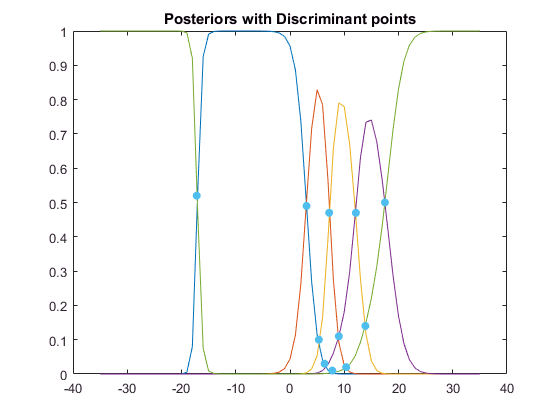

%plotting posteriors with the discriminant points
plot(dummy,post1)
hold on
plot(dummy,post2);
hold on
plot(dummy,post3);
hold on
plot(dummy,post4);
hold on
plot(dummy,post5);
hold on
scatter(discriminants,y,'filled')
hold off
title('Posteriors with Discriminant points')

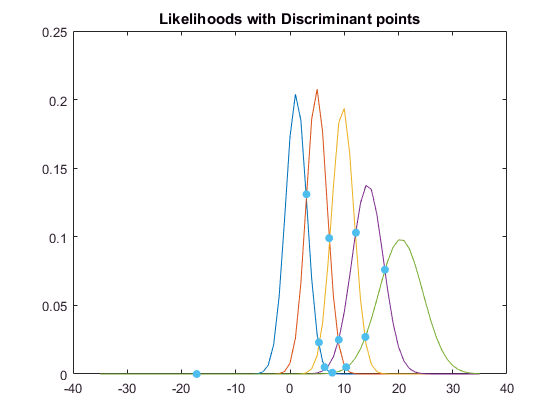

%plotting likelihoods with the SAME discriminant points 
%only y values change since likelilhoods have different y axis than posteriors 
plot(dummy,L1)
hold on
plot(dummy,L2);
hold on
plot(dummy,L3);
hold on
plot(dummy,L4);
hold on
plot(dummy,L5);
hold on
hold on
scatter(discriminants,y1,'filled')
hold off
title('Likelihoods with Discriminant points')

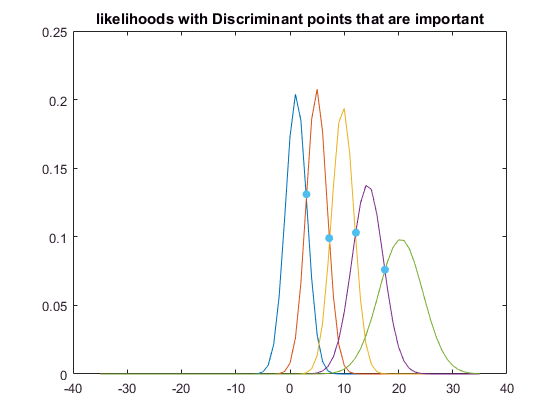

%important points for classification of test data 
impy=[0.131,0.099,0.103,0.076];
impd=[discriminant2,discriminant10,discriminant16,discriminant20];
plot(dummy,L1)
hold on
plot(dummy,L2);
hold on
plot(dummy,L3);
hold on
plot(dummy,L4);
hold on
plot(dummy,L5);
hold on
scatter(impd,impy,'filled')
hold off
title('likelihoods with Discriminant points that are important')

## TEST DATA IMPORTING AND CLASSIFYING USING DISCRIMINANT POINTS METHOD1

Test=load('E:\NUST\Semester 2\machine learning\assignment 2\Assignment-2\test.mat');
datatest=Test.T2;
datatest

datatest =     7.6737   16.5837   -0.5562   21.4121    8.2446
   11.0767   16.8394   -1.1271   22.8690   10.6564
    3.3533   16.1537    2.1060   14.7806   14.7133
    6.2567   13.6766    0.1531   15.9765    9.0683
    3.1152   18.3603    1.7232   23.1627    9.9390
    8.6050   20.2267    0.2962   19.5337   12.8330
    8.8198   14.3977    1.5391   22.2124   12.9256
    2.6749   21.7833   -4.1289   16.1574   11.4711
    9.8874   15.4713    1.9317   13.4648   12.5520
    3.8306   15.2687    4.7071   23.0448   12.2415


%flattening the test data for classification purposes
datatest1=datatest(:);
datatest1(100);


class1test=[];
class2test=[];
class3test=[];
class4test=[];
class5test=[];
count1=0;
count2=0;
count3=0;
count4=0;
count5=0;
for i= 1:100
    if  (datatest1(i)<impd(1))
          class1test(i)=datatest1(i);
          count1=count1+1;
    end
    if (datatest1(i)>impd(1)) && (datatest1(i)<impd(2))
        class2test(i)=datatest1(i);
        count2=count2+1;
    end
    if (datatest1(i)>impd(2)) && (datatest1(i)<impd(3))
        class3test(i)=datatest1(i);
        count3=count3+1;
    end
    if (datatest1(i)>impd(3)) && (datatest1(i)<impd(4))
        class4test(i)=datatest1(i);
        count4=count4+1;
    end
    if (datatest1(i)>impd(4))
        class5test(i)=datatest1(i);
        count5=count5+1;
    end
end
class1testn= class1test(class1test~=0);
class2testn= class2test(class2test~=0);
class3testn= class3test(class3test~=0);
class4testn= class4test(class4test~=0);
class5testn= class5test(class5test~=0);



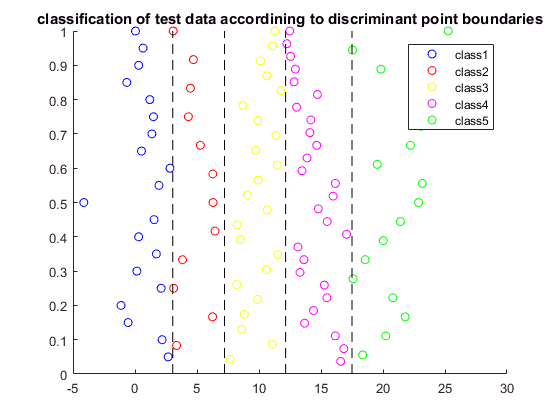

%yvalues for plotting scatter plot selectly by me since test points only x
ytp1=1:1:count1;
ytp2=1:1:count2;
ytp3=1:1:count3;
ytp4=1:1:count4;
ytp5=1:1:count5;
ytp1=ytp1/count1;
ytp2=ytp2/count2;
ytp3=ytp3/count3;
ytp4=ytp4/count4;
ytp5=ytp5/count5;
yforplot=0:0.01:1;
di1=impd(1)*ones(101,1);
di2=impd(2)*ones(101,1);
di3=impd(3)*ones(101,1);
di4=impd(4)*ones(101,1);

scatter(class1testn,ytp1,'b')%class1
hold on
scatter(class2testn,ytp2,'r')%class2
hold on
scatter(class3testn,ytp3,'y')%class3
hold on
scatter(class4testn,ytp4,'m')%class4
hold on
scatter(class5testn,ytp5,'g')%class5
hold on
plot(di1,yforplot,'--','color','k')
hold on
plot(di2,yforplot,'--','color','k')
hold on
plot(di3,yforplot,'--','color','k')
hold on
plot(di4,yforplot,'--','color','k')
hold on

hold off
title('classification of test data accordining to discriminant point boundaries')
legend('class1','class2','class3','class4','class5')

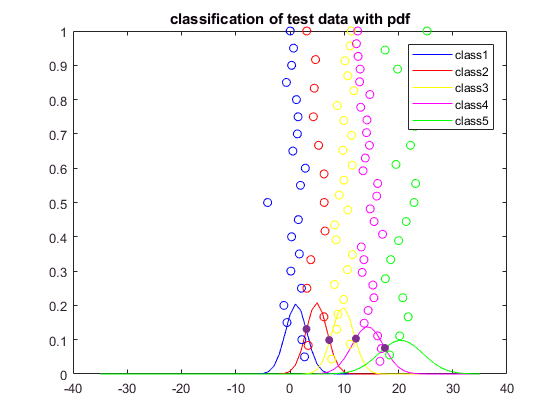

%some points going outside since y is chosen as a random value
%some values are going outside the pdf since the value of y is chosen as randomly
plot(dummy,L1,'color','b')
hold on
plot(dummy,L2,'color','r');
hold on
plot(dummy,L3,'color','y');
hold on
plot(dummy,L4,'color','m');
hold on
plot(dummy,L5,'color','g');
hold on
scatter(class1testn,ytp1,'b')
hold on
scatter(class2testn,ytp2,'r')
hold on
scatter(class3testn,ytp3,'y')
hold on
scatter(class4testn,ytp4,'m')
hold on
scatter(class5testn,ytp5,'g')
hold on
scatter(impd,impy,'filled')
hold off
title('classification of test data with pdf')
legend('class1','class2','class3','class4','class5')

The data is classified perfectly according to the important decision boundaries that were mentioned above

all the data lies near its correct pdf or the same pdf decision region.

This completes method 1 of the assignment

## CLASSIFICATION OF TEST DATA USING DISCRIMININANT FUNCTION APPROACH

## METHOD 2 

class1test1=[];
class2test1=[];
class3test1=[];
class4test1=[];
class5test1=[];
count6=0;
count7=0;
count8=0;
count9=0;
count10=0;
for i= 1:100
    if (abs((datatest1(i)-mean1))< abs((datatest1(i)-mean2))) && (abs((datatest1(i)-mean1))< abs((datatest1(i)-mean3))) && (abs((datatest1(i)-mean1))< abs((datatest1(i)-mean4))) && (abs((datatest1(i)-mean1))< abs((datatest1(i)-mean5)))
        class1test1(i)=datatest1(i);
        count6=count6+1;
    end
    if (abs((datatest1(i)-mean2))< abs((datatest1(i)-mean1))) && (abs((datatest1(i)-mean2))< abs((datatest1(i)-mean3))) && (abs((datatest1(i)-mean2))< abs((datatest1(i)-mean4))) && (abs((datatest1(i)-mean2))< abs((datatest1(i)-mean5)))
        class2test1(i)=datatest1(i);
        count7=count7+1;
    end
    if (abs((datatest1(i)-mean3))< abs((datatest1(i)-mean1))) && (abs((datatest1(i)-mean3))< abs((datatest1(i)-mean2))) && (abs((datatest1(i)-mean3))< abs((datatest1(i)-mean4))) && (abs((datatest1(i)-mean3))< abs((datatest1(i)-mean5)))
        class3test1(i)=datatest1(i);
        count8=count8+1;
    end
    if (abs((datatest1(i)-mean4))< abs((datatest1(i)-mean1))) && (abs((datatest1(i)-mean4))< abs((datatest1(i)-mean2))) && (abs((datatest1(i)-mean4))< abs((datatest1(i)-mean3))) && (abs((datatest1(i)-mean4))< abs((datatest1(i)-mean5)))
        class4test1(i)=datatest1(i);
        count9=count9+1;
    end
    if (abs((datatest1(i)-mean5))< abs((datatest1(i)-mean1))) && (abs((datatest1(i)-mean5))< abs((datatest1(i)-mean2))) && (abs((datatest1(i)-mean5))< abs((datatest1(i)-mean3))) && (abs((datatest1(i)-mean5))< abs((datatest1(i)-mean4)))
        class5test1(i)=datatest1(i);
        count10=count10+1;
    end   
end
class1testn1= class1test1(class1test1~=0);
class2testn1= class2test1(class2test1~=0);
class3testn1= class3test1(class3test1~=0);
class4testn1= class4test1(class4test1~=0);
class5testn1= class5test1(class5test1~=0);

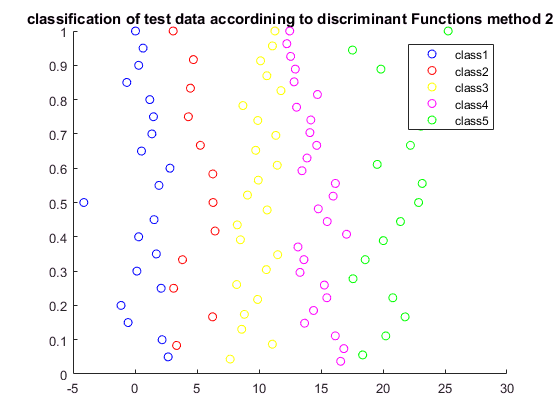

scatter(class1testn1,ytp1,'b')%class1
hold on
scatter(class2testn1,ytp2,'r')%class2
hold on
scatter(class3testn1,ytp3,'y')%class3
hold on
scatter(class4testn1,ytp4,'m')%class4
hold on
scatter(class5testn1,ytp5,'g')%class5
hold off
title('classification of test data accordining to discriminant Functions method 2')
legend('class1','class2','class3','class4','class5')

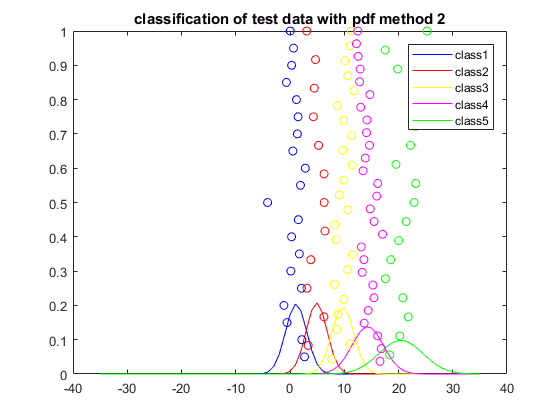

plot(dummy,L1,'color','b')
hold on
plot(dummy,L2,'color','r');
hold on
plot(dummy,L3,'color','y');
hold on
plot(dummy,L4,'color','m');
hold on
plot(dummy,L5,'color','g');
hold on
scatter(class1testn1,ytp1,'b')
hold on
scatter(class2testn1,ytp2,'r')
hold on
scatter(class3testn1,ytp3,'y')
hold on
scatter(class4testn1,ytp4,'m')
hold on
scatter(class5testn1,ytp5,'g')
hold off
title('classification of test data with pdf method 2')
legend('class1','class2','class3','class4','class5')

## PART 3 COMPARISONS

As can be clearly seen from the output of part 2 it is identical to the output in part 1 it completely matches the output in part 1 

which means that this is the correct approach i have made further comparisions between method 1 and method 2 down below for further 

clarificaition

class1testn%method 1 class 1 

class1testn =     2.6749    2.1859   -0.5562   -1.1271    2.1060    0.1531    1.7232    0.2962    1.5391   -4.1289    1.9317    2.8218    0.5205    1.3620    1.4885    1.1928   -0.6609    0.2955    0.6504    0.0387


class1testn1 % method 2 class 1

class1testn1 =     2.6749    2.1859   -0.5562   -1.1271    2.1060    0.1531    1.7232    0.2962    1.5391   -4.1289    1.9317    2.8218    0.5205    1.3620    1.4885    1.1928   -0.6609    0.2955    0.6504    0.0387


class2testn%method 1 class 2 

class2testn =     3.3533    6.2567    3.1152    3.8306    6.4536    6.2944    6.2766    5.2700    4.3038    4.4705    4.7071    3.0786


class2testn1 % method 2 class 2

class2testn1 =     3.3533    6.2567    3.1152    3.8306    6.4536    6.2944    6.2766    5.2700    4.3038    4.4705    4.7071    3.0786


class3testn%method 1 class 3 

class3testn =     7.6737   11.0767    8.6050    8.8198    9.8874    8.1979   10.5913   11.5051    8.5014    8.2446   10.6564    9.0683    9.9390   11.4711    9.7365   11.3578    9.9017    8.7003   11.7695   10.6349   10.1258   11.0835   11.2859


class3testn1 % method 2 class 3

class3testn1 =     7.6737   11.0767    8.6050    8.8198    9.8874    8.1979   10.5913   11.5051    8.5014    8.2446   10.6564    9.0683    9.9390   11.4711    9.7365   11.3578    9.9017    8.7003   11.7695   10.6349   10.1258   11.0835   11.2859


class4testn%method 1 class 4 

class4testn =    16.5837   16.8394   16.1537   13.6766   14.3977   15.4713   15.2687   13.3072   13.6230   13.1411   17.0617   15.4973   14.7806   15.9765   16.1574   13.4648   13.8712   14.6526   14.1046   14.1797   13.0306   14.7133   12.8330   12.9256   12.5520   12.2415   12.4754


class4testn1 % method 2 class 4

class4testn1 =    16.5837   16.8394   16.1537   13.6766   14.3977   15.4713   15.2687   13.3072   13.6230   13.1411   17.0617   15.4973   14.7806   15.9765   16.1574   13.4648   13.8712   14.6526   14.1046   14.1797   13.0306   14.7133   12.8330   12.9256   12.5520   12.2415   12.4754


class5testn%method 1 class 5 

class5testn =    18.3603   20.2267   21.7833   20.7911   17.5824   18.5626   20.0255   21.4121   22.8690   23.1627   19.5337   22.2124   23.0448   24.7732   26.5282   19.8333   17.5380   25.2566


class5testn1 % method 2 class 5

class5testn1 =    18.3603   20.2267   21.7833   20.7911   17.5824   18.5626   20.0255   21.4121   22.8690   23.1627   19.5337   22.2124   23.0448   24.7732   26.5282   19.8333   17.5380   25.2566


## Comparison of the counts of each class in both methods

Method1count=table(count1,count2,count3,count4,count5)

Method1count = 1×5 table
    count1    count2    count3    count4    count5
    ______    ______    ______    ______    ______

    20        12        23        27        18    



Method2count=table(count6,count7,count8,count9,count10)

Method2count = 1×5 table
    count6    count7    count8    count9    count10
    ______    ______    ______    ______    _______

    20        12        23        27        18     


# Conclusion

From this it can be clearly seen that both the methods have achieved the same results

Method 2 is faster than method 1 and it correctly classified all the points with the same level of accuracy

hence, the method 2 discriminant function approach should be used since it is faster and achieves same results

method 1 involved a computation using the quadratic formula for the discriminant points which is additional computation.

Faster and easier method is always preferrable over long and tedious method.